clearvars;clc;

%mnemonic codes
code.fixation = 786;
code.cue_BH = 773;
code.cue_BF = 771;
code.cue_rest = 783;
code.feedback = 781;
modality.offline = 0;
modality.online = 1;
%sub-band of frequencies of psd we are interested in
selected_frequences = (4:2:48)';
channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
num_features = 5;
%load the weigths to select the features
feature_weights = load('features_filter.mat').features_filter';

## find data

%data= load('psd/ai6_psd.mat');
data= load('psd/lezione/ah7_psd.mat');
online = data.online;
offline = data.offline;

## log and sub-frequences extraction

[online.PSD, online.frequences] = extractFrequences(online.PSD, online.frequences, selected_frequences);
online.PSD = log(online.PSD); 

[offline.PSD, offline.frequences] = extractFrequences(offline.PSD, offline.frequences, selected_frequences);
offline.PSD = log(offline.PSD); 

## convert PSDs into dataset for the classifiers

classes = [code.cue_BF, code.cue_BH];
[offline.features, selected_freq_chan_index , fisher_score_run] = psd2features(offline.PSD, offline.run_labels, offline.cue_type_labels, classes, num_features, feature_weights);
% 
% online.features = extractFeatures(online.PSD, selected_freq_chan_index);
%%%% to be equal to the prof
selected_freq_chan_index={[10 9],[11 9],[5 8]};
offline.features=extractFeatures(offline.PSD,selected_freq_chan_index);
online.features = extractFeatures(online.PSD, selected_freq_chan_index);

## compute mean fisher's score

mean_fisher_score = mean(fisher_score_run,3);

## filter mean fisher's score

filtered_mean_Fisher = mean_fisher_score .* feature_weights;

## generate map of selected features

features_matrix = feature_map(selected_freq_chan_index,size(mean_fisher_score));

## Visualization Fisher score

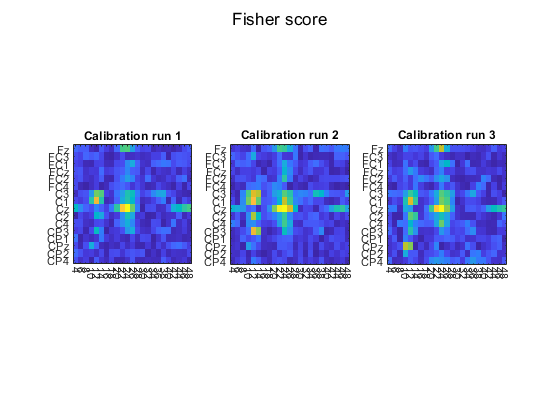

channelId  = 1:length(channel_labels);

NumRuns = length(unique(offline.run_labels));
NumFreqs = length(offline.frequences);
NumChans = length(channel_labels);
classId    = [773 771];
classLb    = {'both hands', 'both feet'};
nclasses   = length(classId);
modalityId = [0 1];
modalityLb = {'offline', 'online'};
OfflineRuns = [1 2 3];
climits = [];
handles = nan(NumRuns, 1);
fig1 = figure;

for rId = 1:length(OfflineRuns)
    subplot(1,3, rId);
    imagesc(fisher_score_run(:, :, OfflineRuns(rId))');
    axis square;
    set(gca, 'XTick', 1:NumFreqs);
    set(gca, 'XTickLabel', offline.frequences);
    set(gca, 'YTick', 1:NumChans);
    set(gca, 'YTickLabel', channel_labels);
    xtickangle(-90);
    
    title(['Calibration run ' num2str(OfflineRuns(rId))]);
    
    climits = cat(2, climits, get(gca, 'CLim'));
    handles(OfflineRuns(rId)) = gca;
    %colorbar;
end
sgtitle('Fisher score');

%set(handles, 'CLim', [min(min(climits)) max(max(climits))]);

## mean fisher score

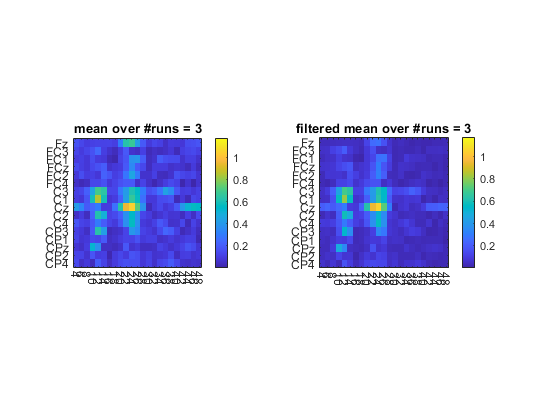


fig2=figure;
subplot(1,2,1);
imagesc(mean_fisher_score');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', offline.frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);
colorbar;
set(gca, 'CLim', [min(min(climits)) max(max(climits))]);

title(['mean over #runs = ' num2str(OfflineRuns(rId))]);

subplot(1,2,2);
imagesc(filtered_mean_Fisher');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', offline.frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);
colorbar;
set(gca, 'CLim', [min(min(climits)) max(max(climits))]);
title(['filtered mean over #runs = ' num2str(OfflineRuns(rId))]);

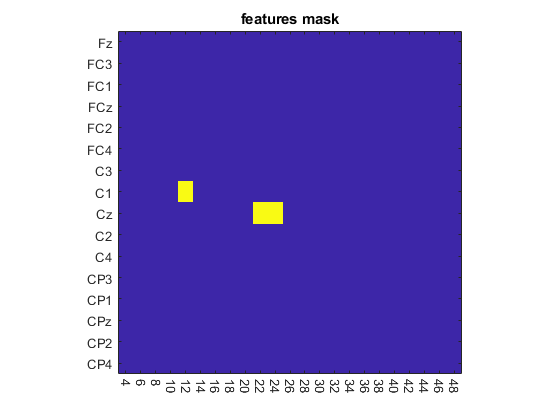


figure3=figure;
imagesc(features_matrix');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', offline.frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);

title('features mask');

## extract training set

bh_index = (offline.cue_type_labels== code.cue_BH);
bf_index = (offline.cue_type_labels== code.cue_BF);

train_set.data = offline.features(bh_index | bf_index, :);
train_set.true_labels = offline.cue_type_labels(bh_index | bf_index);

## train classifier

%model = train_binary_model(train_set, label_train);
model = fitcdiscr(train_set.data, train_set.true_labels, "DiscrimType", "quadratic");

## train set results

predicted_labels = predict(model, train_set.data);
[accuracy, accuracy_per_class] = evaluateClassifier(train_set.true_labels, predicted_labels, classes)

accuracy = 81.8371

accuracy_per_class =    75.9367   87.7358


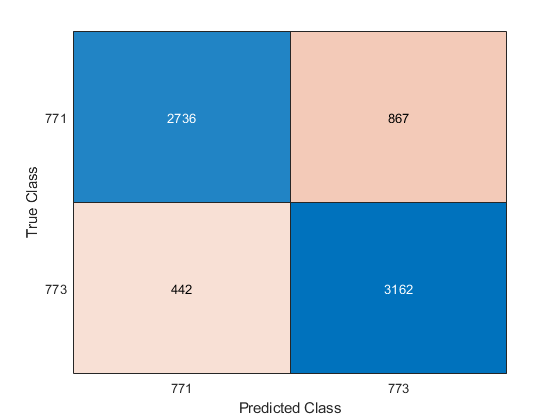

figure;
confusionchart(train_set.true_labels, predicted_labels);

## extract test set

bh_index = (online.cue_type_labels== code.cue_BH);
bf_index = (online.cue_type_labels== code.cue_BF);

test_set.data = online.features(bh_index | bf_index, :);
test_set.true_labels = online.cue_type_labels(bh_index | bf_index);

## test the model on online data

predicted_labels = predict(model, test_set.data);
[accuracy, accuracy_per_class] = evaluateClassifier(test_set.true_labels, predicted_labels, classes)

accuracy = 73.4216

accuracy_per_class =    74.8002   72.5689


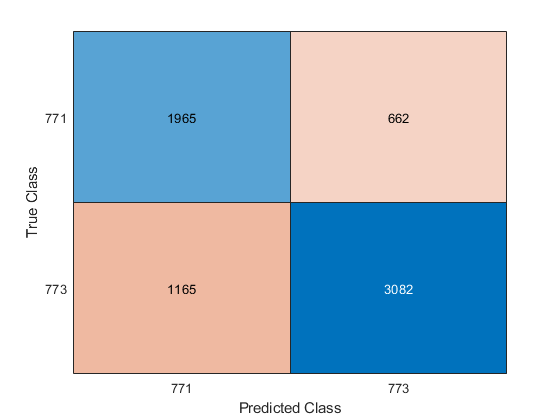

confusionchart(test_set.true_labels, predicted_labels);

# Evidence Accumulation

classify and accumulate evidence over the feedback period of online runs

the evidence accumulation is based on the posterior probability of class 771 both feet

## data

% online data
accumulation_data = online.features;
%predict on data
[a,post_probabilities] = predict(model, accumulation_data);

num_samples = length(accumulation_data);
num_classes = length(classes);
% reset accumulation to the base probability of this class = 1/num_classes
reset_accumulation = 1./num_classes;
% vector of start of feedback for each trial
feedback_starts = online.EVENT.POS(online.EVENT.TYP==code.feedback);

## Exponential smoothing

% coefficient that determines how the system respond to the new sample (high-> conservative, low->responsive)
%alpha_ex = 0.9; 
alpha_ex = 0.97; 
% compute accumulator
accumulator_ex = exponential_smoothing(post_probabilities, num_classes, feedback_starts, alpha_ex);

## Dynamic smoothing

% coefficient that determines how the system respond to the new sample (high-> conservative, low->responsive)
alpha_dyn = 0.5;
beta = 0.11;
conservative_amp = 0.1;
w = 0.3;
free_force_function = @(x) f_free(x,conservative_amp,w);
bmi_force_function = @(x) f_bmi_sin(x);

% compute accumulator
accumulator_dyn = dynamic_smoothing(post_probabilities, num_classes, feedback_starts, alpha_dyn, beta, free_force_function, bmi_force_function);

## moving average

alpha_mov = 0.4;
% compute accumulator
accumulator_mov = mov_avg_smoothing(post_probabilities, num_classes, feedback_starts, alpha_mov);

# EVIDENCE ACCUMULATION PERFORMANCE

## data


% index for the feedback part of the data used in accumulation
feedback_index = getLabelsForEventType(online.EVENT, code.feedback, length(online.PSD));
% vector of true class for the trial
true_class = online.EVENT.TYP(online.EVENT.TYP==code.cue_BF | online.EVENT.TYP==code.cue_BH | online.EVENT.TYP==code.cue_rest);

up_threshold_ex = 0.7;
down_threshold_ex = 0.3;
up_threshold_dyn = 0.77;
down_threshold_dyn = 0.3;
up_threshold_mov = 0.7;
down_threshold_mov = 0.3;

[perf_active_ex, perf_resting_ex, perf_active_rej_ex] = evaluate_accumulation(up_threshold_ex, down_threshold_ex, true_class, accumulator_ex, feedback_index, online.trial_labels)

perf_active_ex = 83.7500

perf_resting_ex = 17.5000

perf_active_rej_ex = 85.8974

[perf_active_dyn, perf_resting_dyn, perf_active_rej_dyn] = evaluate_accumulation(up_threshold_dyn, down_threshold_dyn, true_class, accumulator_dyn, feedback_index, online.trial_labels)

perf_active_dyn = 76.2500

perf_resting_dyn = 2.5000

perf_active_rej_dyn = 77.2152

[perf_active_mov, perf_resting_mov, perf_active_rej_mov] = evaluate_accumulation(up_threshold_mov, down_threshold_mov, true_class, accumulator_mov, feedback_index, online.trial_labels)

perf_active_mov = 67.5000

perf_resting_mov = 2.5000

perf_active_rej_mov = 67.5000

## plot results of evidence accumulation

% fig1 = figure;
% 
% CueClasses    = [771 783 773];
% LbClasses     = {'both feet', 'rest', 'both hands'};
% ValueClasses  = [1 0.5 0];
% Threshold     = 0.7;
% 
% SelTrial = 50;

% Trial 15: good rest
% Trial 80: bad rest
% Trial 55: good both hands
% % Trial 58: good both feet
% 
% cindex = Tk == SelTrial;
% [~, ClassIdx] = ismember(unique(Ck(cindex)), CueClasses);
% 
% GreyColor = [150 150 150]/255;
% LineColors = {'b', 'g', 'r'};
% 
% hold on;
% % Plotting raw probabilities
% plot(pp(cindex, 1), 'o', 'Color', GreyColor);
% 
% % Plotting accumulutated evidence
% plot(ipp(cindex), 'k', 'LineWidth', 2);
% 
% % Plotting actual target class
% yline(ValueClasses(ClassIdx), LineColors{ClassIdx}, 'LineWidth', 5);
% 
% % Plotting 0.5 line
% yline(0.5, '--k');
% 
% % Plotting thresholds
% yline(Threshold, 'k', 'Th_{1}');
% yline(1-Threshold, 'k', 'Th_{2}');
% hold off;
% 
% grid on;
% ylim([0 1]);
% xlim([1 sum(cindex)]);
% legend('raw prob', 'integrated prob');
% ylabel('probability/control')
% xlabel('sample');
% title(['Trial ' num2str(SelTrial) '/' num2str(NumTrials) ' - Class ' LbClasses{ClassIdx} ' (' num2str(CueClasses(ClassIdx)) ')']);

